# Paper2 Function Preparation

## Setting up network

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

%FigurePath = [CurrentFolder '/Figures/Demo022722/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/']; % V1D2
addpath(DataFolder)
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
addpath(DataFolder1)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

CurrentFolder = pwd; % Since loaded data will overwrite pwd...
FigureFolder = [CurrentFolder '/Paper2Figs/']; % V1D2
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2';
    load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))
%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
%load("AllMFPixPara_Paper2TuneFig1V5D1.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
LargeFlag = {'','Large','Larger','LARGER'};
DomList =  {'Small','Large','Larger','LARGER'};
for AngCtgr = 1:4
    for DomCtgr = 1:length(LargeFlag)
        DomFlag = LargeFlag{DomCtgr};
        DomPrint = DomList{DomCtgr};
        AngPrint = AngleList{AngCtgr};
        Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
        L6up = 60; L6low = 6;
        %load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc1_L6c1.mat',AngPrint))
        
        load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc1_L6c1_L6_%d_%d_Cosine_All%s.mat',...
            DataPoint,AngPrint,L6up,L6low,DomFlag))
        a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
        rowsmWin = 30; colswWin = 5;
        MFv = false;
        smth = true;
        if MFv
            LIFN = 5;
        else
            LIFN = 3;
        end

Load and make all 16 functions for this angle

        LGNlist = 4; L6list = 4;
        LDEFrVecS = zeros(length(L4ERcrd),LGNlist,L6list);
        LDEFrVecC = zeros(length(L4ERcrd),LGNlist,L6list);
        LDEFrVecI = zeros(length(L4ERcrd),LGNlist,L6list);
        ContourInfoAll = cell(3,LGNlist,L6list); % Use this for E-I relation
        
        plotFlag = false;
        %CtgrName = {'func1','func2','func3','func4','func5','func6','func7'};
        for LGNCtgr = 1:LGNlist
            figure(LGNCtgr)
            for L6Ctgr = 1:L6list
                %Ctgr = [LGNCtgr,L6Ctgr];
                %load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc%d_L6c%d.mat',...
                %                                           AngPrint,LGNCtgr,L6Ctgr))
                if exist(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All%s.mat',...
                        DataPoint,AngPrint,LGNCtgr,L6Ctgr,L6up,L6low,DomFlag)) > 0
                load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All%s.mat',...
                    DataPoint,AngPrint,LGNCtgr,L6Ctgr,L6up,L6low,DomFlag))
                else %% 22.5: (1 4) (2 3) switchable
                    disp("Warning! File non exists, using replacement...")
                    switch L6Ctgr
                        case 1
                            load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All%s.mat',...
                                DataPoint,AngPrint,LGNCtgr,4,L6up,L6low,DomFlag))
                        case 2
                            load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All%s.mat',...
                                DataPoint,AngPrint,LGNCtgr,3,L6up,L6low,DomFlag))
                        case 3
                            load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All%s.mat',...
                                DataPoint,AngPrint,LGNCtgr,2,L6up,L6low,DomFlag))
                        case 4
                            load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All%s.mat',...
                                DataPoint,AngPrint,LGNCtgr,1,L6up,L6low,DomFlag))
                    end
                end
                L4EPlot = reshape(L4ERcrd,a2,a1);
                L4IPlot = reshape(L4IRcrd,a2,a1);
                FrLDE = zeros(length(f_EnIOut),LIFN);
                for LDEInd = 1:length(f_EnIOut)
                    if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
                        FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
                    else
                        FrLDE(LDEInd,:) = nan;
                    end
                end
                FrLDE(FrLDE<0) = eps;
                % S rates
                subplot(L6list,3,(L6Ctgr-1)*3+1)
                [LDEFrVecS(:,LGNCtgr,L6Ctgr), ContourInfoAll{1,LGNCtgr,L6Ctgr}]= ...
                    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                    LGNCtgr,L6Ctgr,'S',smth,plotFlag,MFv, [rowsmWin, colswWin] );
                
                % C rates
                subplot(L6list,3,(L6Ctgr-1)*3+2)
                [LDEFrVecC(:,LGNCtgr,L6Ctgr), ContourInfoAll{2,LGNCtgr,L6Ctgr}] = ...
                    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                    LGNCtgr,L6Ctgr,'C',smth,plotFlag,MFv, [rowsmWin, colswWin] );
                
                % I rates
                subplot(L6list,3,(L6Ctgr-1)*3+3)
                [LDEFrVecI(:,LGNCtgr,L6Ctgr), ContourInfoAll{3,LGNCtgr,L6Ctgr}] = ...
                    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                    LGNCtgr,L6Ctgr,'I',smth,plotFlag,MFv, [rowsmWin, colswWin] );
            end
        end
        close all

Create a function

        L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
        L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
        [L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
        
        % 2D function now, depending on input of total E and I kick numbers\
        ItplType = 'Linear';
        for LGNCtgr = 1:LGNlist
            for L6Ctgr = 1:L6list
                LDEFrfunc.S{LGNCtgr,L6Ctgr} = ...
                    griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                LDEFrfunc.C{LGNCtgr,L6Ctgr} = ...
                    griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                LDEFrfunc.I{LGNCtgr,L6Ctgr} = ...
                    griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
            end
        end
        %% If 22.5...may need to introduce symmetry
        if Angle == 22.5
            LDEFrfuncUse.S = FuncSwap(LDEFrfunc.S,[1,2,3,4;4,3,2,1]);
            LDEFrfuncUse.C = FuncSwap(LDEFrfunc.C,[1,2,3,4;4,3,2,1]);
            LDEFrfuncUse.I = FuncSwap(LDEFrfunc.I,[1,2,3,4;4,3,2,1]);
            LDEFrfunc = LDEFrfuncUse;
        end
        save([SaveFolder sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomPrint)],...
            'LDEFrfunc','L4EmeshX','L4ImeshY')
    end
end

#### Bg precomputed 

LargeFlag = {'Smaller','Small','Large'};
LIFN = 3;
for DomCtgr = 1:length(LargeFlag)
    DomFlag = LargeFlag{DomCtgr};
    load(sprintf('Paper2_LIFoLDE_Fig4BgV4D2_%s.mat',DomFlag))
    
    a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
    rowsmWin = 10; colswWin = 5;
    if DomCtgr == 1
        rowsmWin = 25; colswWin = 10;
        
    end
    
    MFv = false;
    smth = true;
    plotFlag = true;
    
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),LIFN);
    
    for LDEInd = 1:length(f_EnIOut)
        if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    FrLDE(FrLDE<0) = eps;
    % S rates
    subplot 131
    [LDEFrVecS, ~]= ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
        [],[],'S',smth,plotFlag,MFv, [rowsmWin, colswWin] );
    
    % C rates
    subplot 132
    [LDEFrVecC, ~] = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
        [],[],'C',smth,plotFlag,MFv, [rowsmWin, colswWin] );
    
    % I rates
    subplot 133
    [LDEFrVecI, ~] = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
        [],[],'I',smth,plotFlag,MFv, [rowsmWin, colswWin] );
    
    close all

Create a function

    L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
    L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
    [L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
    
    % 2D function now, depending on input of total E and I kick numbers\
    ItplType = 'Linear';

    LDEFrfunc.S = ...
        griddata(L4ERcrd,L4IRcrd,LDEFrVecS,L4EmeshX, L4ImeshY,ItplType);
    LDEFrfunc.C = ...
        griddata(L4ERcrd,L4IRcrd,LDEFrVecC,L4EmeshX, L4ImeshY,ItplType);
    LDEFrfunc.I = ...
        griddata(L4ERcrd,L4IRcrd,LDEFrVecI,L4EmeshX, L4ImeshY,ItplType);


    save([SaveFolder sprintf('FuncBG_%s_SM%d_%d.mat',DomFlag,rowsmWin,colswWin)],...
        'LDEFrfunc','L4EmeshX','L4ImeshY')
end

Additionally, make a mesh plot to demo the domains

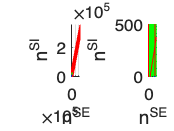

close all

AngleList = {'0.0','7.5','15.0','22.5'};
LargeFlag = {'','Large','Larger','LARGER'};
DomList =  {'Small','Large','LARGER'};
EdgeColors = {'b','g','r'};
AngCtgr = 1;
figure
for DomCtgr = length(DomList):-1:1
    DomFlag = LargeFlag{DomCtgr};
    DomPrint = DomList{DomCtgr};
    AngPrint = AngleList{AngCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
    L6up = 60; L6low = 6;
    %load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc1_L6c1.mat',AngPrint))

    load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc1_L6c1_L6_%d_%d_Cosine_All%s.mat',...
        DataPoint,AngPrint,L6up,L6low,DomFlag))
    a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
    L4EPlot = reshape(L4ERcrd,a2,a1)*0.1468;
    L4IPlot = reshape(L4IRcrd,a2,a1)*0.3350; % these are for S only
    subplot 121
    hold on
    mesh(L4EPlot,L4IPlot,zeros(size(L4EPlot)),...
        'EdgeColor',EdgeColors{DomCtgr},'FaceAlpha',0.0)
    ylim([0 3.6e5]);xlim([0,2.3e5])
    xlabel('n^{SE}');ylabel('n^{SI}');grid on
    set(gca,'FontSize',17)
end

for DomCtgr = 1:length(DomList)
    DomFlag = LargeFlag{DomCtgr};
    DomPrint = DomList{DomCtgr};
    AngPrint = AngleList{AngCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
    L6up = 60; L6low = 6;
    %load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc1_L6c1.mat',AngPrint))

    load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc1_L6c1_L6_%d_%d_Cosine_All%s.mat',...
        DataPoint,AngPrint,L6up,L6low,DomFlag))
    a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
    L4EPlot = reshape(L4ERcrd,a2,a1)*0.1468;
    L4IPlot = reshape(L4IRcrd,a2,a1)*0.3350; % these are for S only

    subplot 122
    hold on
    mesh(L4EPlot+DomCtgr,L4IPlot+DomCtgr,zeros(size(L4EPlot)),...
        'EdgeColor',EdgeColors{DomCtgr},'FaceAlpha',0.0)
    axis([0 500 0 500*50/36])
    xlabel('n^{SE}');ylabel('n^{SI}')
    set(gca,'FontSize',17)

end